# Performance Caceres

Description: This algorithm check and plot data for theoretical  and actual performance based on the incident radiation

[https://re.jrc.ec.europa.eu/pvg_tools/en/tools.html](https://re.jrc.ec.europa.eu/pvg_tools/en/tools.html)

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 12/2021

clc
clear
close all

load Y2019.mat
load Y2020.mat
load Y2021.mat

% Nominal capacity
Nom_Cap=[957.6]; %[kW] 

% Power output table
CF_2019=table2array(Y2019(:,end))/(24); %kW
CF_2020=table2array(Y2020(:,end))/(24);
CF_2021=table2array(Y2021(:,end))/(24);

% Make Timetable
CF_2019=table2timetable([Y2019(:,1),array2table(CF_2019)]);
CF_2020=table2timetable([Y2020(:,1),array2table(CF_2020)]);
CF_2021=table2timetable([Y2021(:,1),array2table(CF_2021)]);


## Daily, Weekly, Monthly

% 2019
Daily_2019=retime(CF_2019,'daily','mean');
Weekly_2019=retime(CF_2019,'weekly','mean');
Monthly_2019=retime(CF_2019,'monthly','mean');
Year_2019= retime(CF_2019,'yearly','mean');

% 2020
Daily_2020=retime(CF_2020,'daily','mean');
Weekly_2020=retime(CF_2020,'weekly','mean');
Monthly_2020=retime(CF_2020,'monthly','mean');
Year_2020= retime(CF_2020,'yearly','mean');

% 2021
Daily_2021=retime(CF_2021,'daily','mean');
Weekly_2021=retime(CF_2021,'weekly','mean');
Monthly_2021=retime(CF_2021,'monthly','mean');
Year_2021= retime(CF_2021,'yearly','mean');


Days=[31 28 31 30 31 30 31 31 30 31 30 31]; 

% Average 2005 2015
I_ref=[127	135	172	186	230	252	298	271	203	156	122	121]*1000./(24*Days)

I_ref =   170.6989  200.8929  231.1828  258.3333  309.1398  350.0000  400.5376  364.2473  281.9444  209.6774  169.4444  162.6344


mean(I_ref)

ans = 259.0611

I_Ref=I_ref*Nom_Cap/1000

I_Ref =   163.4613  192.3750  221.3806  247.3800  296.0323  335.1600  383.5548  348.8032  269.9900  200.7871  162.2600  155.7387


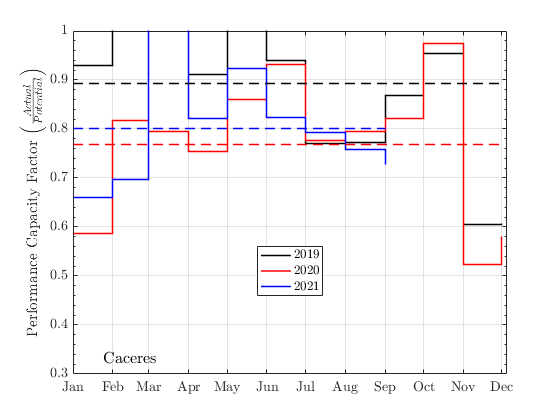


figure
stairs(Monthly_2019.VarName1,Monthly_2019.CF_2019./I_Ref','k','LineWidth',1.5)
hold on
stairs(Monthly_2019.VarName1,Monthly_2020.CF_2020./I_Ref','r','LineWidth',1.5)
stairs(Monthly_2019.VarName1(1:9),Monthly_2021.CF_2021./I_Ref(1:9)','b','LineWidth',1.5)
stairs(Monthly_2019.VarName1,mean(Monthly_2019.CF_2019./I_Ref')*ones(1,12),'--k','LineWidth',1.5)
stairs(Monthly_2019.VarName1,mean(Monthly_2020.CF_2020./I_Ref')*ones(1,12),'--r','LineWidth',1.5)
stairs(Monthly_2019.VarName1(1:9),mean(Monthly_2021.CF_2021./I_Ref(1:9)')*ones(1,9),'--b','LineWidth',1.5)
ylabel('Performance Capacity Factor $\Big( \frac{Actual}{Potential} \Big)$','Interpreter','latex')
datetick('x','mmm')
xlim([datetime('1-Jan-2019') datetime('5-Dec-2019')])
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',...
    0.13,'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
legend('2019','2020','2021','location','best','interpreter','latex')
text(23,0.33,'Caceres','Color',[0 0 0],'Interpreter','latex','FontSize',16)
ylim([0.3 1])
print('-dpng','-r400','Performance_CF_Caceres.png')

% Overall mean
mean([mean(Monthly_2019.CF_2019./I_Ref')
mean(Monthly_2020.CF_2020./I_Ref')
mean(Monthly_2021.CF_2021./I_Ref(1:9)')])

ans = 0.8207